load Data_USEconVECModel.mat

Data = FRED;                        % Assign dates and raw data
Data.GDP = 100*log(FRED.GDP);       % GDP (output)
Data.GDPDEF = 100*log(FRED.GDPDEF); % GDP implicit price deflator
Data.COE = 100*log(FRED.COE);       % Compensation of employees (wages)
Data.HOANBS = 100*log(FRED.HOANBS); % Hours of all persons (hours)
Data.PCEC = 100*log(FRED.PCEC);     % Personal consumption expenditures (consumption)
Data.GPDI = 100*log(FRED.GPDI);     % Gross private domestic investment (investment)


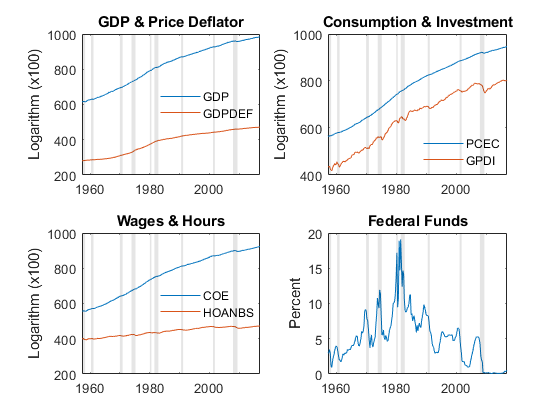

figure
subplot(2,2,1)
plot(Data.Time, [Data.GDP, Data.GDPDEF])
recessionplot
title('GDP & Price Deflator')
ylabel('Logarithm (x100)')
h = legend('GDP','GDPDEF','Location','Best');
h.Box = 'off';

subplot(2,2,2);
plot(Data.Time, [Data.PCEC Data.GPDI])
recessionplot
title('Consumption & Investment')
ylabel('Logarithm (x100)')
h = legend('PCEC','GPDI','Location','Best');
h.Box = 'off';

subplot(2,2,3)
plot(Data.Time, [Data.COE Data.HOANBS])
recessionplot
title('Wages & Hours')
ylabel('Logarithm (x100)')
h = legend('COE','HOANBS','Location','Best');
h.Box = 'off';

subplot(2,2,4)
plot(Data.Time, Data.FEDFUNDS)
recessionplot
title('Federal Funds')
ylabel('Percent')

P = 2;                % The number of VEC(P-1) model lags
Y = Data.Variables;   % Extract all data from the timetable for convenience
[h,pValue,stat,cValue,mleHstar] = jcitest(Y, 'lags', P-1, 'Model', 'H*');


************************
Results Summary (Test 1)

Data: Y
Effective sample size: 238
Model: H*
Lags: 1
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  266.1410  150.5530 0.0010   0.3470  
1  1  164.7259  117.7103 0.0010   0.2217  
2  1  105.0660  88.8042  0.0028   0.1665  
3  0  61.7326   63.8766  0.0748   0.1323  
4  0  27.9494   42.9154  0.6336   0.0446  
5  0  17.0919   25.8723  0.4470   0.0379  
6  0  7.9062    12.5174  0.2927   0.0327  


[h,pValue,stat,cValue,mleH1] = jcitest(Y, 'lags', P-1, 'Model', 'H1');


************************
Results Summary (Test 1)

Data: Y
Effective sample size: 238
Model: H1
Lags: 1
Statistic: trace
Significance level: 0.05


r  h  stat      cValue   pValue   eigVal   
----------------------------------------
0  1  261.9245  125.6176 0.0010   0.3460  
1  1  160.8737  95.7541  0.0010   0.2212  
2  1  101.3621  69.8187  0.0010   0.1661  
3  1  58.1247   47.8564  0.0045   0.1323  
4  0  24.3440   29.7976  0.1866   0.0446  
5  0  13.4866   15.4948  0.0982   0.0340  
6  1  5.2631    3.8415   0.0219   0.0219  


r = 4;                   % Cointegrating rank
uLogL = mleHstar.r4.rLL; % Loglikelihood of the unrestricted H* model for r = 4
rLogL = mleH1.r4.rLL;    % Loglikelihood of the restricted H1 model for r = 4

[h,pValue,stat,cValue] = lratiotest(uLogL, rLogL, r)

h = logical
   0


pValue = 0.9618

stat = 0.6111

cValue = 9.4877

R = [zeros(1,size(Y,2))  1]';  % Constraint matrix
[h,pValue,stat,cValue] = jcontest(Y,r,'BCon',R,'Model','H*','Lags',P-1)

h = logical
   0


pValue = 0.9618

stat = 0.6111

cValue = 9.4877



[Mdl,se] = estimate(vecm(size(Y,2),r,P-1), Y, 'Model', 'H1');

toFit = vecm(Mdl.NumSeries, Mdl.Rank, Mdl.P - 1);

toFit.Constant(abs(Mdl.Constant ./ se.Constant) < 2) = 0;
toFit.ShortRun{1}(abs(Mdl.ShortRun{1} ./ se.ShortRun{1}) < 2) = 0;
toFit.Adjustment(abs(Mdl.Adjustment ./ se.Adjustment) < 2) = 0;

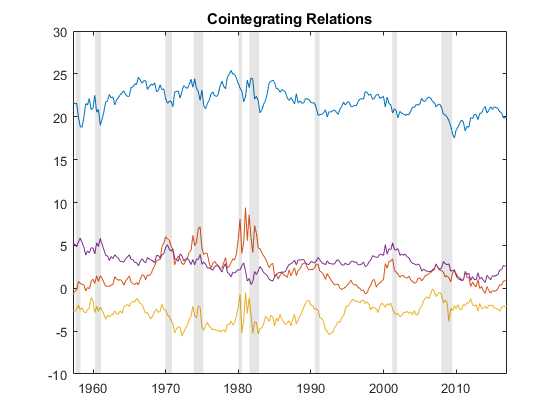

Fit = estimate(toFit, Y, 'Model', 'H1');

B = [Fit.Cointegration ; Fit.CointegrationConstant' ; Fit.CointegrationTrend'];
figure
plot(Data.Time, [Y ones(size(Y,1),1) (-(Fit.P - 1):(size(Y,1) - Fit.P))'] * B)
recessionplot
title('Cointegrating Relations')

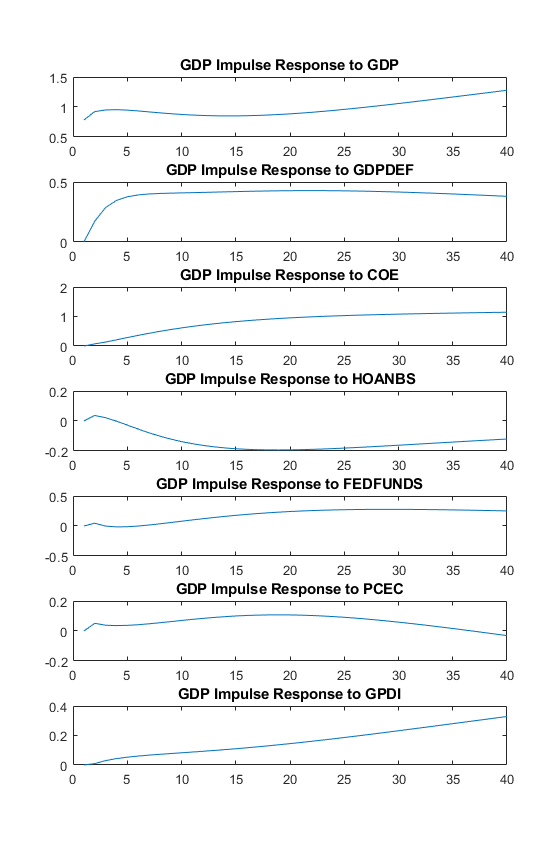

horizon = 40;

VAR = varm(Fit);
IRF = armairf(VAR.AR, {}, 'InnovCov',  VAR.Covariance, 'NumObs', horizon);

h = figure;
iSeries = 1;            % Column 1 is associated with GDP series
for i = 1:Mdl.NumSeries
    subplot(Mdl.NumSeries,1,i)
    plot(IRF(:,iSeries,i))
    title("GDP Impulse Response to " + Data.Properties.VariableNames(i))
end

screen = get(h,'Parent');
set(h,'Position',[h.Position(1) screen.MonitorPositions(4)*0.1 h.Position(3) screen.MonitorPositions(4)*0.8]);

Y = Data;                   % Work directly with the timetable
T0 = datetime(1976,12,31);  % Initialize forecast origin (31-Dec-1976 = (1976,12,31) triplet)
T = T0;
horizon = 4;                % Forecast horizon in quarters (4 = 1 year)
numForecasts = numel(Y.Time(timerange(T,Y.Time(end),'closed'))) - horizon;
yForecast = nan(numForecasts, horizon, Mdl.NumSeries);

for t = 1:numForecasts
%
%   Get the end-of-quarter dates for the current forecast origin.
%
    quarterlyDates = timerange(Y.Time(1), T, 'closed');
%
%   Estimate the VEC model.
%
    Fit = estimate(toFit, Y(quarterlyDates,:).Variables, 'Model', 'H1');
%
%   Forecast the model at each quarter out to the forecast horizon.
%
%   Store the forecasts for the current origin (T) as a 3-D array in which
%   the 1st page stores all forecasts for the 1st series (GDP), the 2nd page
%   stores all forecasts for the 2nd series (GDPDEF), and so forth. This
%   storage convention facilitates the access of data from the timetable
%   of forecasts created below.
%
    yForecast(t,:,:) = forecast(Fit, horizon, Y(quarterlyDates,:).Variables);
%
%   Update the forecast origin to include the data of the next quarter.
%
    T = dateshift(T, 'end', 'quarter', 'next');
end

originDates = dateshift(T0, 'end', 'quarter', (0:(numForecasts-1))');

forecastDates = NaT(numForecasts,horizon);
for i = 1:horizon
    forecastDates(:,i) = dateshift(originDates, 'end', 'quarter', i);
end

Forecast = timetable(forecastDates,'RowTimes',originDates, 'VariableNames', {'Times'});
for i = 1:size(Y,2)
    Forecast.(Y.Properties.VariableNames{i}) = yForecast(:,:,i);
end

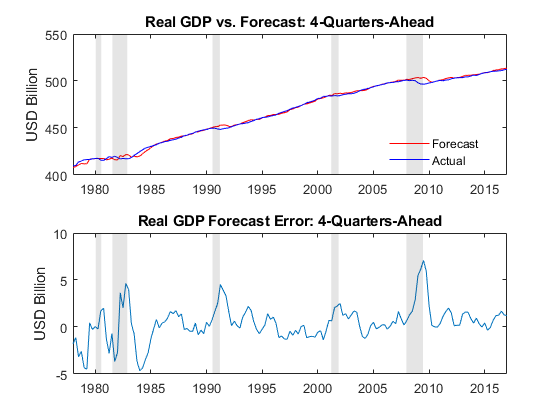

forecastRealGDP = Forecast.GDP(:,4) - Forecast.GDPDEF(:,4);
realGDP = Y(Forecast.Times(:,4),:).GDP - Y(Forecast.Times(:,4),:).GDPDEF;

figure
subplot(2,1,1)
plot(Forecast.Times(:,4), forecastRealGDP, 'r')
hold on
plot(Forecast.Times(:,4), realGDP, 'b')
title('Real GDP vs. Forecast: 4-Quarters-Ahead')
ylabel('USD Billion')
recessionplot
h = legend('Forecast','Actual','Location','Best');
h.Box = 'off';

subplot(2,1,2)
plot(Forecast.Times(:,4), forecastRealGDP - realGDP)
title('Real GDP Forecast Error: 4-Quarters-Ahead')
ylabel('USD Billion')
recessionplot

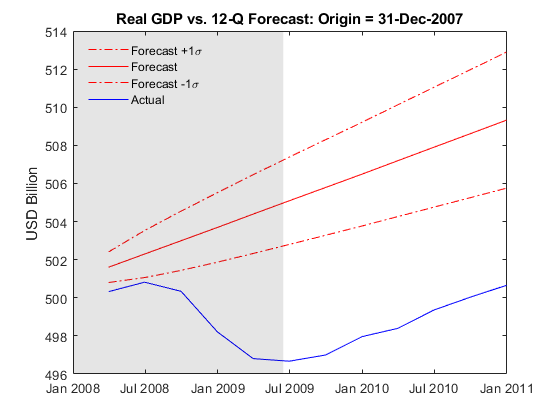

horizon = 12;  % 12 quarters = 3 years (Table 3 of Smets & Wouters [13])

T = datetime(2007,12,31);  % Forecast origin just prior to the crisis (31-Dec-2007 = (2007,12,31) triplet)
Fit = estimate(toFit, Y(timerange(Y.Time(1),T,'closed'),:).Variables, 'Model', 'H1');
[yForecast, yMSE] = forecast(Fit, horizon, Y(timerange(Y.Time(1),T,'closed'),:).Variables);

sigma = zeros(horizon,1);  % Forecast standard errors
for i = 1:horizon
    sigma(i) = sqrt(yMSE{i}(1,1) - 2*yMSE{i}(1,2) + yMSE{i}(2,2));
end

forecastDates = dateshift(T, 'end', 'quarter', 1:horizon);
figure
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) + sigma, '-.r')
hold on
plot(forecastDates,  yForecast(:,1) - yForecast(:,2), 'r')
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) - sigma, '-.r')
plot(forecastDates, Y(forecastDates,:).GDP - Y(forecastDates,:).GDPDEF, 'b')
title("Real GDP vs. 12-Q Forecast: Origin = " + string(T))
ylabel('USD Billion')
recessionplot
h = legend('Forecast +1\sigma', 'Forecast', 'Forecast -1\sigma', 'Actual', 'Location', 'Best');
h.Box = 'off';

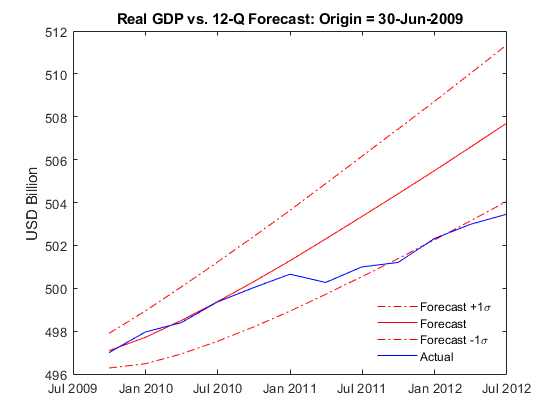

T = datetime(2009,6,30);  % Forecast origin just after the crisis (30-Jun-2009 = (2009,6,30) triplet)
Fit = estimate(toFit, Y(timerange(Y.Time(1),T,'closed'),:).Variables, 'Model', 'H1');
[yForecast, yMSE] = forecast(Fit, horizon, Y(timerange(Y.Time(1),T,'closed'),:).Variables);

sigma = zeros(horizon,1); % Forecast standard errors
for i = 1:horizon
    sigma(i) = sqrt(yMSE{i}(1,1) - 2*yMSE{i}(1,2) + yMSE{i}(2,2));
end

forecastDates = dateshift(T, 'end', 'quarter', 1:horizon);
figure
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) + sigma, '-.r')
hold on
plot(forecastDates,  yForecast(:,1) - yForecast(:,2), 'r')
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) - sigma, '-.r')
plot(forecastDates, Y(forecastDates,:).GDP - Y(forecastDates,:).GDPDEF, 'b')
title("Real GDP vs. 12-Q Forecast: Origin = " + string(T))
ylabel('USD Billion')
h = legend('Forecast +1\sigma', 'Forecast', 'Forecast -1\sigma', 'Actual', 'Location', 'Best');
h.Box = 'off';

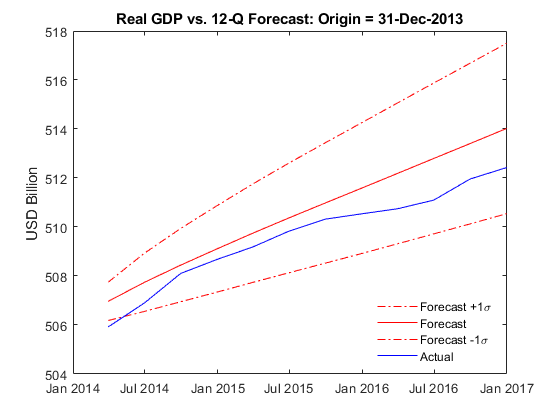

T = dateshift(Data.Time(end), 'end', 'quarter', -horizon);
Fit = estimate(toFit, Y(timerange(Y.Time(1),T,'closed'),:).Variables, 'Model', 'H1');
[yForecast, yMSE] = forecast(Fit, horizon, Y(timerange(Y.Time(1),T,'closed'),:).Variables);

sigma = zeros(horizon,1);        % Forecast standard errors
for i = 1:horizon
    sigma(i) = sqrt(yMSE{i}(1,1) - 2*yMSE{i}(1,2) + yMSE{i}(2,2));
end

forecastDates = dateshift(T, 'end', 'quarter', 1:horizon);
figure
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) + sigma, '-.r')
hold on
plot(forecastDates,  yForecast(:,1) - yForecast(:,2), 'r')
plot(forecastDates, (yForecast(:,1) - yForecast(:,2)) - sigma, '-.r')
plot(forecastDates, Y(forecastDates,:).GDP - Y(forecastDates,:).GDPDEF, 'b')
title("Real GDP vs. 12-Q Forecast: Origin = " + string(T))
ylabel('USD Billion')
h = legend('Forecast +1\sigma', 'Forecast', 'Forecast -1\sigma', 'Actual', 'Location', 'Best');
h.Box = 'off';

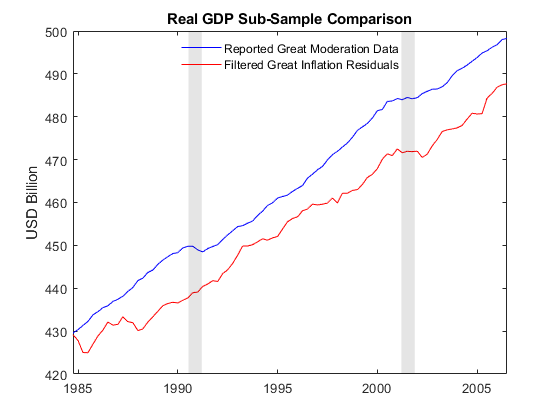

T1 = datetime(1979,6,30);                     % Last quarter of Great Inflation (30-Jun-1979 = (1979,6,30) triplet)
Y1 = Y(timerange(Y.Time(1),T1,'closed'),:);   % Great Inflation data
[Fit1,~,~,E1] = estimate(toFit, Y1.Variables, 'Model', 'H1');

T2 = datetime(1984,3,31);                     % First quarter of Great Moderation (31-Mar-1984 = (1984,3,31) triplet)
Y2 = Y(timerange(T2,Y.Time(end),'closed'),:); % Great Moderation data
Fit2 = estimate(toFit, Y2.Variables, 'Model', 'H1');

YY = filter(Fit2, E1, 'Y0', Y2(1:Fit2.P,:).Variables, 'Scale', false);
Y2 = Y2((Fit2.P + 1):(size(E1,1) + Fit2.P),:);  % Extract relevant data for convenient comparison
YY = array2timetable(YY, 'RowTimes', Y2.Time, 'VariableNames', Y.Properties.VariableNames);


figure
plot(YY.Time, Y2.GDP - Y2.GDPDEF, 'b')
hold on
plot(YY.Time, YY.GDP - YY.GDPDEF, 'r')
title('Real GDP Sub-Sample Comparison')
ylabel('USD Billion')
recessionplot
h = legend('Reported Great Moderation Data', 'Filtered Great Inflation Residuals', 'Location', 'Best');
h.Box = 'off';

YF = CBO;                        % Assign the dates and raw data
YF.GDP = 100*log(CBO.GDP);       % GDP (output)
YF.GDPDEF = 100*log(CBO.GDPDEF); % GDP implicit prices deflator
YF.COE = 100*log(CBO.COE);       % Compensation of employees (wages)

YF(end-3:end,:)

ans = 4×7 timetable
        Time        GDP      GDPDEF     COE      HOANBS    FEDFUNDS    PCEC    GPDI
    ___________    ______    ______    ______    ______    ________    ____    ____

    31-Mar-2027    1023.5     492.1    963.14    NaN       2.8         NaN     NaN 
    30-Jun-2027    1024.4     492.6    964.07    NaN       2.8         NaN     NaN 
    30-Sep-2027    1025.4    493.09    964.99    NaN       2.8         NaN     NaN 
    31-Dec-2027    1026.3    493.59    965.89    NaN       2.8         NaN     NaN 


YF.GDP(:) = NaN;
YF(end-3:end,:)

ans = 4×7 timetable
        Time       GDP    GDPDEF     COE      HOANBS    FEDFUNDS    PCEC    GPDI
    ___________    ___    ______    ______    ______    ________    ____    ____

    31-Mar-2027    NaN     492.1    963.14    NaN       2.8         NaN     NaN 
    30-Jun-2027    NaN     492.6    964.07    NaN       2.8         NaN     NaN 
    30-Sep-2027    NaN    493.09    964.99    NaN       2.8         NaN     NaN 
    31-Dec-2027    NaN    493.59    965.89    NaN       2.8         NaN     NaN 




forecastQuarters = timerange(Y.Time(end),CBO.Time(end),'openleft');

YF = YF(forecastQuarters,:);
yForecast = forecast(Fit2, size(YF,1), Y.Variables, 'YF', YF.Variables);

yForecast = array2timetable(yForecast, 'RowTimes', YF.Time, 'VariableNames', Y.Properties.VariableNames);

yForecast(end-3:end,:)

ans = 4×7 timetable
        Time        GDP      GDPDEF     COE      HOANBS    FEDFUNDS     PCEC      GPDI 
    ___________    ______    ______    ______    ______    ________    ______    ______

    31-Mar-2027    1024.1     492.1    963.14    488.27    2.8         987.67    837.48
    30-Jun-2027      1025     492.6    964.07    488.69    2.8          988.6    838.42
    30-Sep-2027    1025.9    493.09    964.99    489.05    2.8          989.5    838.98
    31-Dec-2027    1026.7    493.59    965.89     489.4    2.8         990.38    839.51


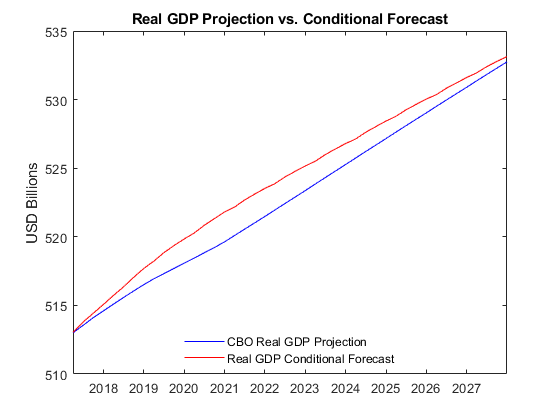

figure
plot(YF.Time, 100*log(CBO(forecastQuarters,:).GDP) - YF.GDPDEF, 'b')
hold on
plot(YF.Time, yForecast.GDP - yForecast.GDPDEF, 'r')
title('Real GDP Projection vs. Conditional Forecast')
ylabel('USD Billions')
h = legend('CBO Real GDP Projection', 'Real GDP Conditional Forecast', 'Location', 'Best');
h.Box = 'off';

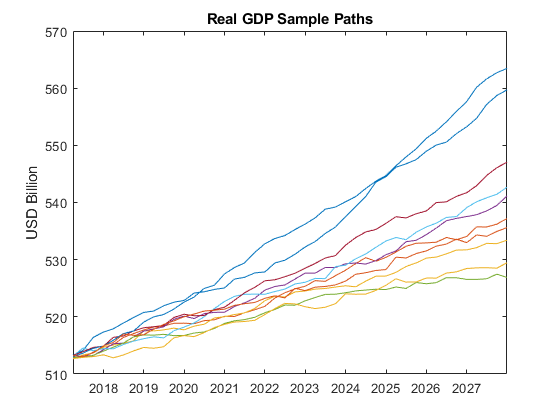

rng default
YY = simulate(Fit2, size(YF,1), 'Y0', Y.Variables, 'YF', YF.Variables, 'NumPaths', 1000);


figure
for i = 1:10
    plot(YF.Time, YY(:,1,i) - YY(:,2,i))
    hold on
end
title('Real GDP Sample Paths')
ylabel('USD Billion')

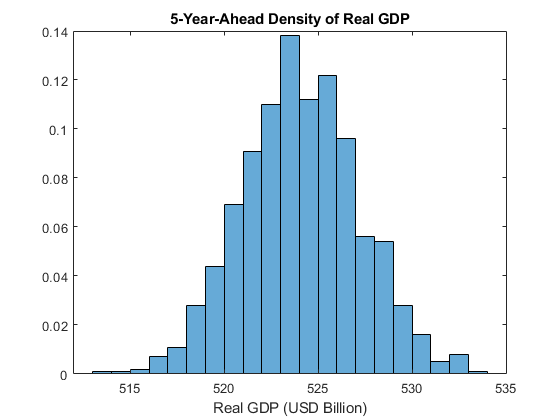

YY = permute(squeeze(YY(20,:,:)), [2 1]);
figure
histogram(YY(:,1) - YY(:,2), 'Normalization', 'pdf')
xlabel('Real GDP (USD Billion)')
title('5-Year-Ahead Density of Real GDP')